clearvars; close('all');
% ADCP data
fname='data\ADCP.nc';
finfo = ncinfo(fname);
% NAV data
fname='data\nav.csv';
nav=readtable(fname,'PreserveVariableNames',true);

load cs_data.mat

% plot from sig review files

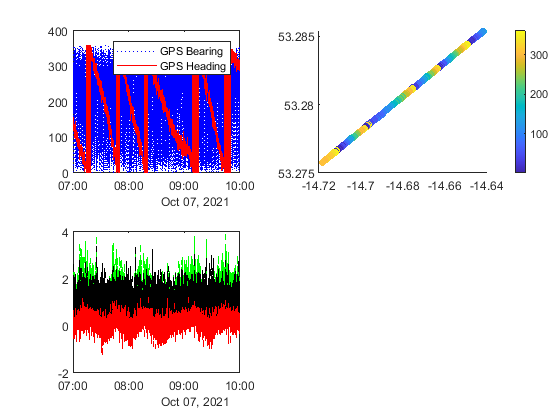

% plot from nav csv files
figure;
X=nav.LON; Y=nav.LAT; B=nav.GPSBearing;H=nav.GPSHeading;ADV=nav.adcpVel;
ASV=nav.asvVel;

T= datetime(nav.Date_Time,'InputFormat','yyyy-MM-dd''T''hh:mm:ss.SS');
DateVector = datevec(T);

B(B>360)=nan;B(B<0)=nan;H(H>360)=nan;H(H<0)=nan;
L=nav.LAT;
ik = L<55 & L>53; % CS
ix = DateVector(:,2)==10 & DateVector(:,3)==7;% 7th Oct
iy = ismember(DateVector(:,4),[7,8,9]); 
id = ix & ik & iy;
% L=nav.LAT;id = L>57.05 & L<57.25; %RT
nexttile;
h1=plot(T(id),B(id),'b:');
hold on
h2=plot(T(id),H(id),'r-');
legend('GPS Bearing','GPS Heading');

nexttile;
scatter(X(id),Y(id),30,H(id),'filled');
colorbar
nexttile;
h3=plot(T(id),ADV(id),'--g');
hold on
h4=plot(T(id),ASV(id),'--k');
h5=plot(T(id),ADV(id)-ASV(id),'--r');

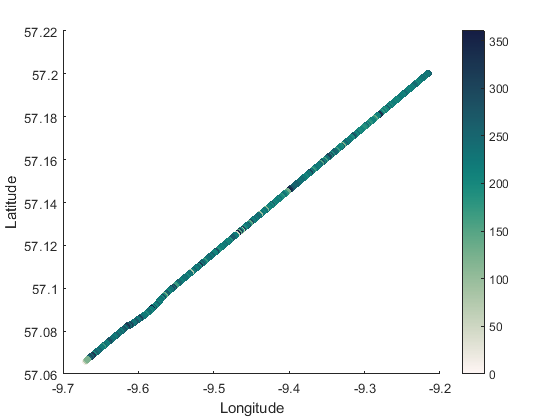

% make scatter plot
X=nav.LON; Y=nav.LAT; Z=nav.Dir_avg;
id = Y>57.05 & Y<57.25;
scatter(X(id),Y(id),30,Z(id),'filled');
colormap(cmocean('temp'));
C=colorbar;
xlabel('Longitude')
ylabel('Latitude');ylabel(C,'Average current direction (degrees)');

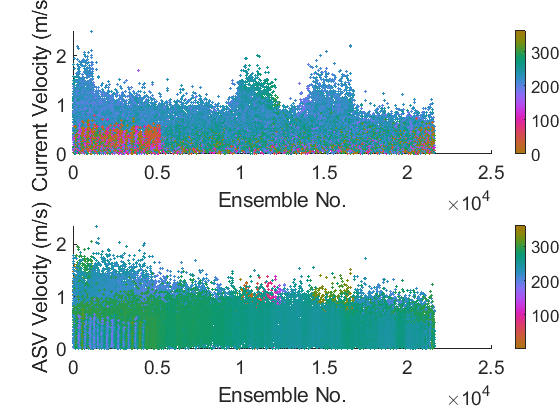

figure;
nexttile;
X=nav.EnsNo; Y=nav.Vel_avg; Z=nav.Dir_avg;
L=nav.LAT;id = L>57.05 & L<57.25;
scatter(X(id),Y(id),5,Z(id),'filled');
colormap(cmocean('phase'));
C=colorbar;
xlabel('Ensemble No.')
ylabel('Current Velocity (m/s)')
ylabel(C,'Average current direction (degrees)');
set(gca,'FontSize',14)
nexttile;
magnitude = sqrt(((nav.GPSEast).^2)+((nav.GPSNorth).^2));
X=nav.EnsNo; Y=magnitude; Z=nav.GPSHeading;
L=nav.LAT;id = L>57.05 & L<57.25;
scatter(X(id),Y(id),5,Z(id),'filled');
colormap(cmocean('phase'));
C=colorbar;
xlabel('Ensemble No.')
ylabel('ASV Velocity (m/s)');
ylabel(C,'GPS heading (degrees)');

set(gca,'FontSize',14)

vels=ncread(fname,'vel');

Error using netcdflib
The NetCDF library encountered an error during execution of 'open' function - 'Unknown file format (NC_ENOTNC)'.
Error in netcdf.open (line 67)
        [varargout{:}] = netcdflib ( 'open', filename, varargin{1} );
Error in internal.matlab.imagesci.nc/openToRead (

range=ncread(fname,'range');
time=ncread(fname,'time');

vel_e_av=vels(:,:,1);
vel_n_av=vels(:,:,2);
% [dir,spd] = cart2pol(vel_e_av,vel_n_av)

magnitude = sqrt(((vel_e_av).^2)+((vel_e_av).^2));

heading = ncread(fname,'heading')


figure;

vel_e_av =     0.7624
    0.1598
   -0.6066
    0.0026
   -1.0457
    0.1733
   -0.4607
   -0.1665
   -1.0418
   -0.0360



%% plotvelocity
x=time';
y=binD(:,1);
figure('Renderer', 'painters', 'Position', [10 20 1600 600])
z=v_E/100;
subplot(2,1,1);
imagesc(x,y,z);  
c=colorbar;
caxis([-2 2]);
cmocean('balance','pivot',0);
datetick('x','HH:MM dd-mmm','keeplimits');
ylabel('Depth')
ylabel(c,'')
grid on
title([name ' Velocity East' ]);

subplot(2,1,2);
z=v_N/100;
imagesc(x,y,z);  
c=colorbar;
caxis([-2 2]);
cmocean('balance','pivot',0)
datetick('x','HH:MM dd-mmm','keeplimits');
ylabel('Depth')
ylabel(c,'')
grid on
title([name ' Velocity North' ]);
print(gcf,'-dpng',['figures/' name '_Velocities2']);
